clear;
T = readtable("g_edges.csv","TextType", "string", "ReadVariableNames", false);
g = digraph(T.Var1, T.Var2);
p = plot(g)

p =   GraphPlot with properties:

     NodeColor: [0 0.4470 0.7410]
    MarkerSize: 2
        Marker: 'o'
     EdgeColor: [0 0.4470 0.7410]
     LineWidth: 0.5000
     LineStyle: '-'
     NodeLabel: {}
     EdgeLabel: {}
         XData: [1×126 double]
         YData: [1×126 double]
         ZData: [1×126 double]

  Show all properties


shortpath = shortestpath(g, 'NED','TYRION');
g.Nodes.NodeColors = (2*sqrt(indegree(g)-min(indegree(g)))+0.2)

g =   digraph with properties:

    Edges: [549×1 table]
    Nodes: [126×2 table]


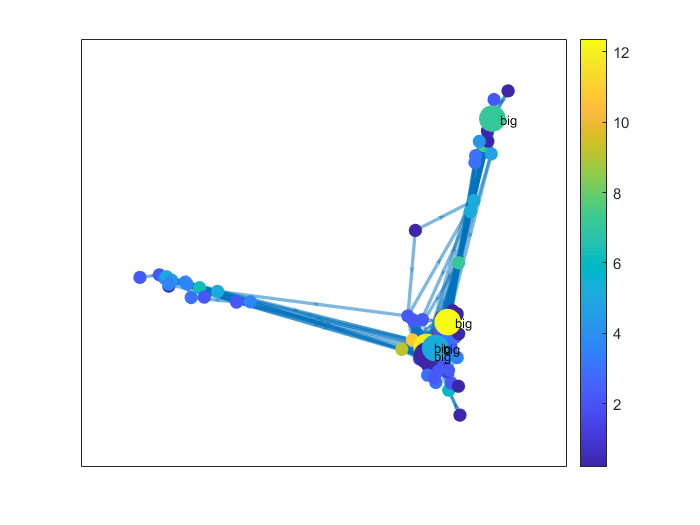

p.MarkerSize = 7;
p.LineWidth = 2;
colorbar
G = g;
highlight(p,shortpath,'EdgeColor','r', "LineWidth", 6);
for i = 1:5
    num = find(indegree(G) == max(indegree(G)));
    highlight(p, num, 'MarkerSize',15);
    labelnode(p, num, 'big')
    G = rmnode(G,find(indegree(G) == max(indegree(G))));
end
p.NodeCData = g.Nodes.NodeColors;